Mp = 0.12;
zeta = -log(Mp)/(sqrt(pi^2 + log(Mp)^2))

zeta = 0.5594

ts = 2;
Wn = 4/(ts*zeta)

Wn = 3.5752

beta = acos(zeta);
beta = rad2deg(beta);
xpoint = -zeta*Wn

xpoint = -2

tan_beta = tan((beta*pi)/180);
ypoint = tan_beta*zeta*Wn

ypoint = 2.9634

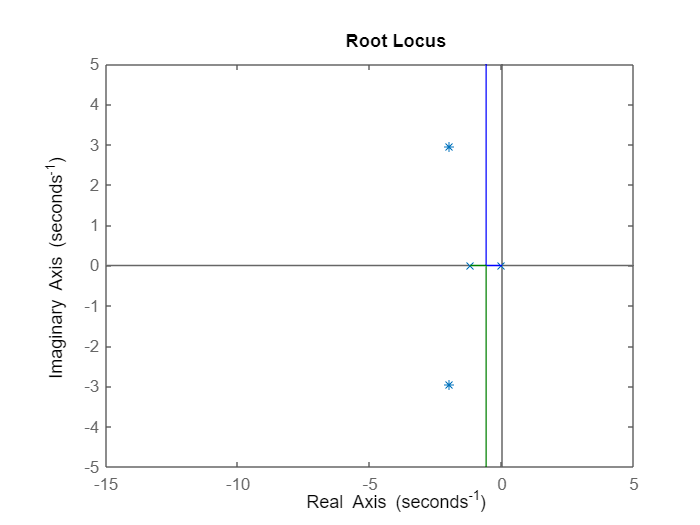

num1 = 15.25;
den1 = [1 1.2 0];
g1 = tf (num1,den1);
rlocusplot (g1);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

%sisotool(g1)

teta_p = 37;
teta_z = 87;
x = ypoint/(tan((44.5*pi)/180));
p = x + 1

p = 4.0156

y = ypoint/(tan((77.5*pi)/180));
z = y + 1

z = 1.6570

s = -2 + 2.96j ;
num2 = 15.25*(s+z);
den2 = (s+p)*s*(s+1.2);
k = abs(den2/num2)

k = 0.8632

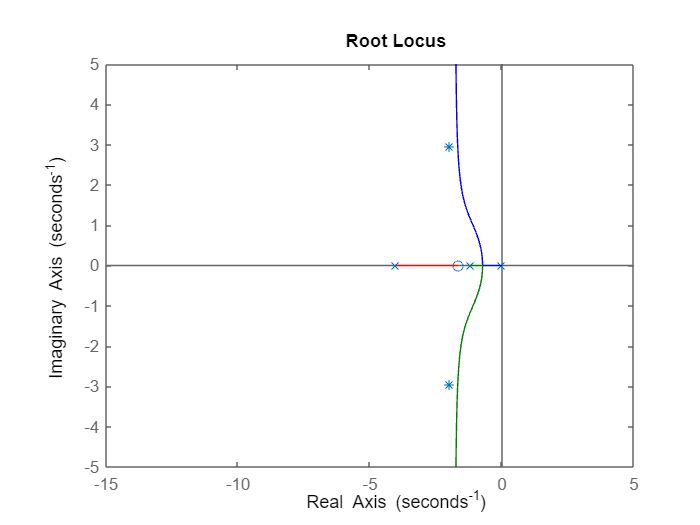

num3 = [k*15.25 k*15.25*z];
den3 = [1 1.2+p 1.2*p 0];
g2 = tf(num3,den3);
rlocusplot (g2);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

%sisotool(g2);

K_old = (k*15.25*z)/(1.2*p);
K_new = 34;
z2 = -xpoint/12

z2 = 0.1667

p2 = (z2*K_old)/K_new

p2 = 0.0222

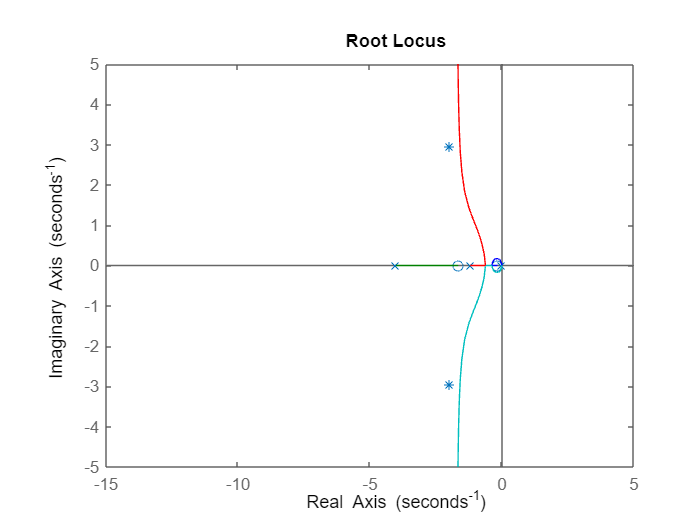

num4 = [k*15.25 (k*15.25)*(z+z2) k*15.25*z*z2];
den4 = [1 1.2+p+p2 (1.2*(p+p2))+(p*p2) 1.2*p*p2 0];
g3 = tf(num4,den4);
h = rlocusplot (g3);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

sisotool(g3)